clc; clear; close all;

% Lens parameters
n0 = 1.0;          
n_edge = 0.561;    
H = 22*(sin(pi/3)*9.708);         
h = H/2;           

Nrows = 11;        

% Gradient parameter
alpha = (1/h)*acosh(n0/n_edge);

% Row positions
row_width = H/Nrows;
y = linspace(-h + row_width/2, h - row_width/2, Nrows);

%hyperbolic secant profile
n_sech = n0 .* sech(alpha .* y);

%reduced-aberration profile
b1 = -0.0679;
b2 = -0.002;

z = alpha .* y;
g = z ./ (1 + b1.*z.^2 + b2.*z.^4);

n_reduced = n0 .* sech(g);

%% Display table
T = table((1:Nrows)', y', n_sech', n_reduced', ...
    'VariableNames', {'RowID','y_position_m','n_hyperbolic_secant','n_reduced_aberration'});

disp(T);

    RowID    y_position_m    n_hyperbolic_secant    n_reduced_aberration
    _____    ____________    ___________________    ____________________

      1        -84.074             0.61197                0.56696       
      2        -67.259             0.71828                0.69511       
      3        -50.444             0.82317                0.81427       
      4        -33.629             0.91436                0.91232       
      5        -16.815             0.97737                0.97724       
      6              0                   1                      1       
      7         16.815             0.97737                0.97724       
      8         33.629             0.91436                0.91232       
      9         50.444             0.82317                0.81427       
     10         67.259             0.71828                0.

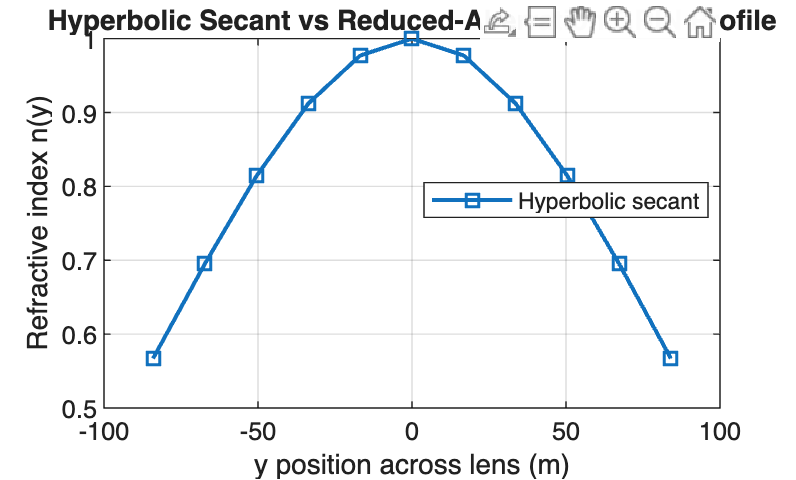


%% Plot profiles
figure;

plot(y, n_reduced, 's-', 'LineWidth', 1.5);
grid on;
xlabel('y position across lens (m)');
ylabel('Refractive index n(y)');
title('Hyperbolic Secant vs Reduced-Aberration GRIN Profile');
legend('Hyperbolic secant','Reduced aberration','Location','best');


%% Helper function
function y = sech(x)
    y = 1 ./ cosh(x);
end